# Dynamic chip thickness

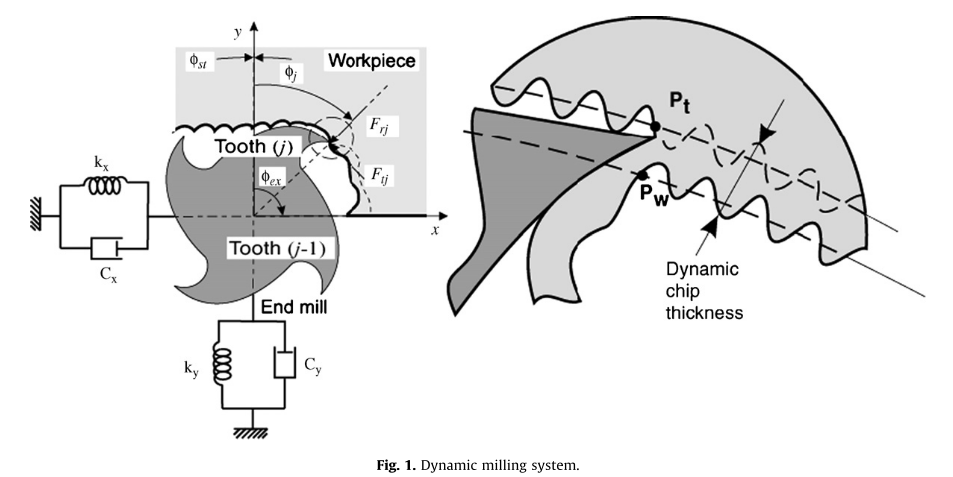

stepSize = .1;

phi_ex = 180; % exit immersion angles of
phi_st = 0; % start immersion angles of

x = [1:stepSize:100];
y = x.^2;
phi_j = linspace(0,360*5, length(x)-1);


% function h_j = h_j()
deltaX  = x(2:end) - x(1:end-1);
deltaY  = y(2:end) - y(1:end-1);

g = @(phi_j) ((phi_j < phi_ex) & (phi_st < phi_j)); % (2)
h_j = (deltaX .* sind(phi_j) + deltaY .* cosd(phi_j)) .* g(phi_j); % (1)
% end


